# **drawHDim**

Draw horizontal dimension

## Description

Horizontal dimension measures  the horizontal distance between two points.

## Syntax

drawHDim(form,d1,d2,x1,y1,x2,y2,xt,yt)

drawHDim(__,'-str',str)

drawHDim(_,LineSpec)

### Description

drawHDim(form,d1,d2,x1,y1,x2,y2,xt,yt) draw horizontal dimension between points (x1,y1) and (x2,y2) and locate text, i.e. value of distnce x2-x1, at point (xt,yt). If x2 < x1 than the points are swaped.

drawHDim(__,'-str',str) draw horizontal dimension between points (x1,y1) and (x2,y2) and locate text given by variable str at point (xt,yt).

drawHDim(__,LineSpec)  sets the line style, line width, and color.

### Method

drawHDim use drawLine, drawArrohwhead, and gkText to draw a horizontal dimension . For drawing text the function drawHDim use current text attrubtes. They can be changed by function drawSet.

## Arguments

### Input Arguments

**form **- arrowhead form

**d1,d2 **- arrow head width and height

**x1,y1 **- start point. x1 colud be > x2

**x2,y2 **- end point

**xt,yt    **- text location. If xt is inside interval (x1,x2) then text is located at the center of the interval

### Optional Name-Value Pair Input Arguments

**'-str'|'-txt',str** - dimension text

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

## Examples

### Example 1

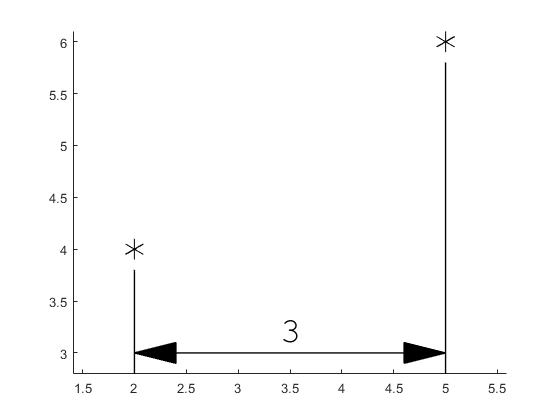

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 4;
x2 = 5; y2 = 6;
xt = 3; yt = 3;
gkSet('FontSize',26)
drawPoint(1,ad1/2,x1,y1)
drawPoint(1,ad1/2,x2,y2)
drawHDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt)

%grid on

### Example 2

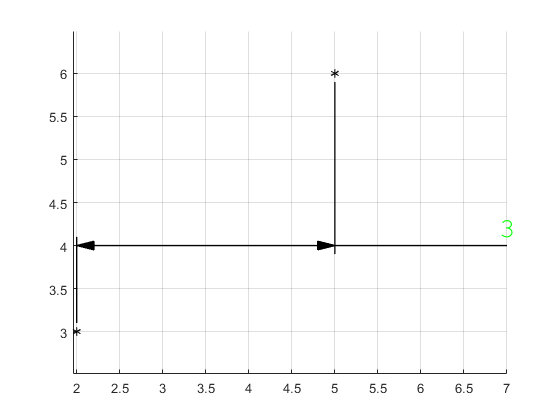

drawInit
ad1 = 0.2; ad2 = ad1/2;
x1 = 2; y1 = 3;
x2 = 5; y2 = 6;
xt = 7; yt = 4;
drawSet('FontSize',20,'textColor','g')
drawPoint(1,ad1/2,x1,y1)
drawPoint(1,ad1/2,x2,y2)
drawHDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt)
grid on

### Example 3

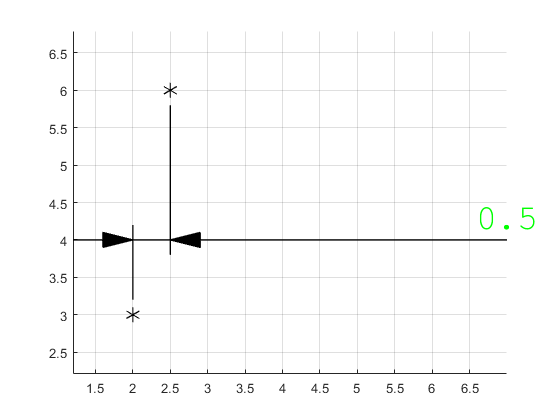

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 3;
x2 = 2.5; y2 = 6;
xt = 7; yt = 4;
drawSet('FontSize',26)
drawPoint(1,ad1/2,x1,y1)
drawPoint(1,ad1/2,x2,y2)
drawHDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt)
grid on

### Example 4

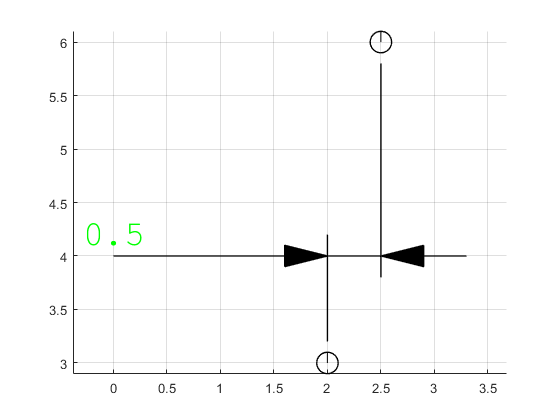

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 3;
x2 = 2.5; y2 = 6;
xt = 0; yt = 4;
drawSet('FontSize',26)
drawPoint(3,ad2,x1,y1)
drawPoint(3,ad2,x2,y2)
drawHDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt)
grid on

### Example 5

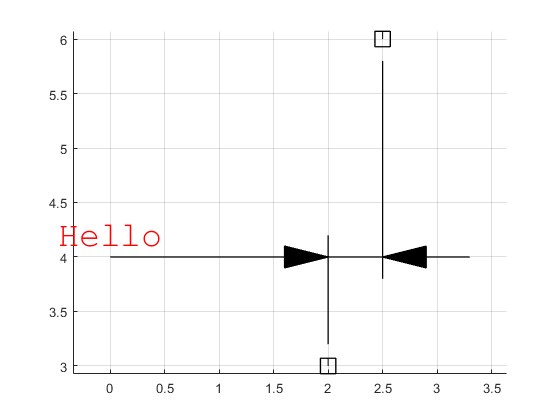

drawInit
ad1 = 0.4; ad2 = ad1/2;
x1 = 2; y1 = 3;
x2 = 2.5; y2 = 6;
xt = 0; yt = 4;
drawSet('FontSize',26,'textColor','r')
drawPoint(2,ad1/2,x1,y1)
drawPoint(2,ad1/2,x2,y2)
drawHDim(3,ad1,ad2,x1,y1,x2,y2,xt,yt,'-str','Hello')
grid on

### Example 6

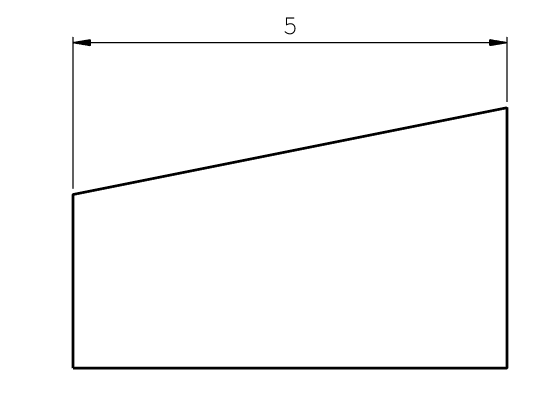

drawInit
ad1 = 0.2; ad2 = ad1/3;
a = 5; b = 2; c = 3;
p = drawPolygon([0 a a 0],[0 0 c b],'LineWidth',2,'Color','k');
drawSet('FontSize',20,'textColor','k')
drawHDim(3,ad1,ad2,p.xk(3),p.yk(3),p.xk(4),p.yk(4),a/2,1.25*c)
axis off

%grid on

## See also

## References